# Homework #2

## Problem 1 (25 points) 

In this problem, we explore the complexity and accuracy of the linear interpolation algorithm on uniform (equidistant) grids.  In the code block below, you're given the following elements in the workspace:

x: point at which the interpolant has to be evaluated. 

x1: left limit x1 of the interval (x1 ≤ x) 

xN: right limit xN of the interval (x ≤ xN) 

N: number of segments 

xi: the N+1 points subdividing the domain into N segments

fi: (N+1) ×1 array of function values f(xi), with i = 1...N +1 

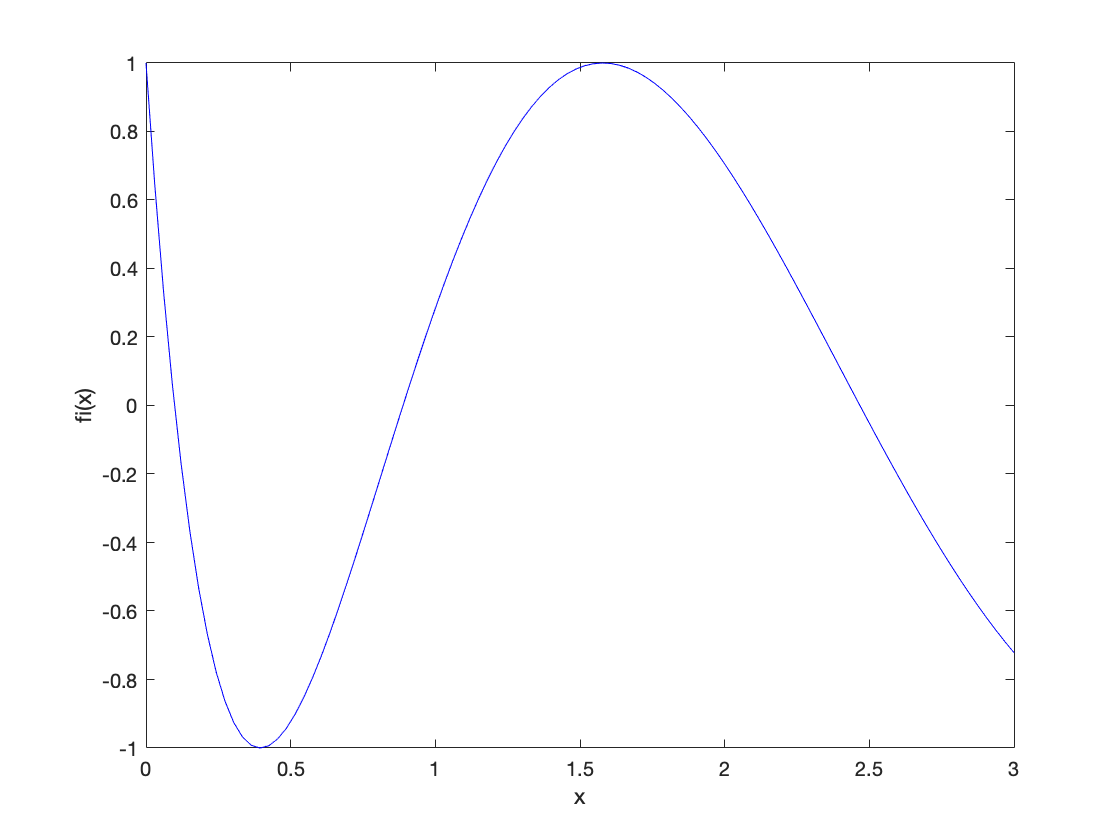

clear all
close all
x1=0;
xN=3;
N=99;
xi=linspace(x1,xN,N+1);
fi=cos(5*sqrt(xi));
plot(xi,fi,'b')
xlabel('x')
ylabel('fi(x)')

a) (5 points) Write a block of code implementing linear interpolation on a uniform grid.  You should create code that takes a value of x and gives us If(x) stored ina  variable named "Ifx"  Use your code to compute the value If(xq) where xq=0.2571. 

xq=0.2571;
% Place your code here
ix = 1;
x = xi(1);
while x < xq
    ix = ix+1;
    x = xi(ix);
end
ix = ix - 1;
x = xi(ix);

Ifx = fi(ix)+((fi(ix+1))-fi(ix))./((xi(ix+1)-x)).*(xq-x)

Ifx = -0.8188

b) (5 points) Learn how to use the interp1 function and verify the correctness of your solution to part (a). 

% Place you code here
Ifx2 = interp1(xi,fi,xq,"linear");

if round(Ifx,4) == round(Ifx2,4)
    a = "is equal"
else
    a = "not equal"
end

a = "is equal"

c) (5 points) In order to accurately estimate the execution time of our interpolation code, we need to run it multiple times. Time the execution of 10^4 interpolation operations for N = 100 and N =10000 and verify that it does not change signiﬁcantly with N and so the complexity is consistent with O(1).

NOTE:  When you construct this test, it's important not to include generation of the vectors xi and fi as part of the "interpolation operations" being evaluated. 

% Here is a starter code
% We checked the execution time of 10^4 calls to sort
N=10^2;
x1=0;
xN=3;
xi=linspace(x1,xN,N+1);
fi=cos(5*sqrt(xi));
xq=0.2571;
ix = 1;
x = xi(1);
tic
while x < xq
    ix = ix+1;
    x = xi(ix);
end
ix = ix - 1;
x = xi(ix);

Ifx = fi(ix)+((fi(ix+1))-fi(ix))./((xi(ix+1)-x)).*(xq-x);
toc

Elapsed time is 0.015264 seconds.


tic
Ifx2 = interp1(xi,fi,xq,"linear");
toc

Elapsed time is 0.006231 seconds.



N=10^4;
x1=0;
xN=3;
xi=linspace(x1,xN,N+1);
fi=cos(5*sqrt(xi));
xq=0.2571;
ix = 1;
x = xi(1);
tic
while x < xq
    ix = ix+1;
    x = xi(ix);
end
ix = ix - 1;
x = xi(ix);

Ifx = fi(ix)+((fi(ix+1))-fi(ix))./((xi(ix+1)-x)).*(xq-x);
toc

Elapsed time is 0.011741 seconds.


tic
Ifx2 = interp1(xi,fi,xq,"linear");
toc

Elapsed time is 0.007603 seconds.


% This data suggests that "sort" is O(N) since a 100X increase in the list size
% led to roughly a 100X increase in execution time.  The growth is a bit faster 
% than linear, but this is not important for our purposes here.

% This data suggests that "interp1" is O(1) since a 100x increase in the
% list size led to roughly a 1x increase in execution time.

d) (5 points) Create a uniform grid with N = 10 points on [0,1] and use it to generate the fi table for the function cos(5*sqrt(xi)). Carry out linear interpolation where the query points are 10,000 randomly generated values on [0,3] (NOTE: you can re-use your code from part (a) or else use the MATLAB built-in interp1).  Find the worst-case (maximal) error for the 10,000 randomly generated points.  Save your result in a variable emax10.

Hint: Use max and abs functions to estimate the error.


xr=3*rand(10000,1); % 10,000 randomly generated values over [0,3]
% Place your code here
N = 10;
grid = linspace(0,1,N);
fi = cos(5*sqrt(grid));
emax10 = 0;
for ix = 1:length(xr)
    xq = xr(ix);
    interpval = interp1(grid,fi,xq,"linear");
    error = abs(cos(5*sqrt(xq))-interpval);
    if error > emax10
        emax10 = error;
    end
end
emax10

emax10 = 0.0699

e) (5 points) Repeat the analysis from (d) for ﬁner grids with N = 100 and N = 1000. What is the order of accuracy of this algorithm? (HINT: read "Interpolation_sect_2_Convergence.mlx" if you are not sure what “order of accuracy” means). Save your results in variables emax100 and emax1000.  Record your corresponding discretization parameters in variables named h 10, h100, and h1000.Generate a plot of the maximum error as a function of 1/h similar to ﬁgure 4 of the reading assignment). Use a log-log scale with clear labels and a title.

Hint: MATLAB has a built in function "loglog" that can generate a log-log scale plot.

% Place your code here
xr=3*rand(10000,1); % 10,000 randomly generated values over [0,3]
% Place your code here
N = 100;
grid = linspace(0,1,N);
fi = cos(5*sqrt(grid));
emax100 = 0;
for ix = 1:length(xr)
    xq = xr(ix);
    interpval = interp1(grid,fi,xq,"linear");
    error = abs(cos(5*sqrt(xq))-interpval);
    if error > emax100
        emax100 = error;
    end
end
emax100

emax100 = 6.5487e-04


xr=3*rand(10000,1); % 10,000 randomly generated values over [0,3]
% Place your code here
N = 1000;
grid = linspace(0,1,N);
fi = cos(5*sqrt(grid));
emax1000 = 0;
for ix = 1:length(xr)
    xq = xr(ix);
    interpval = interp1(grid,fi,xq,"linear");
    error = abs(cos(5*sqrt(xq))-interpval);
    if error > emax1000
        emax1000 = error;
    end
end
emax1000

emax1000 = 6.4995e-06

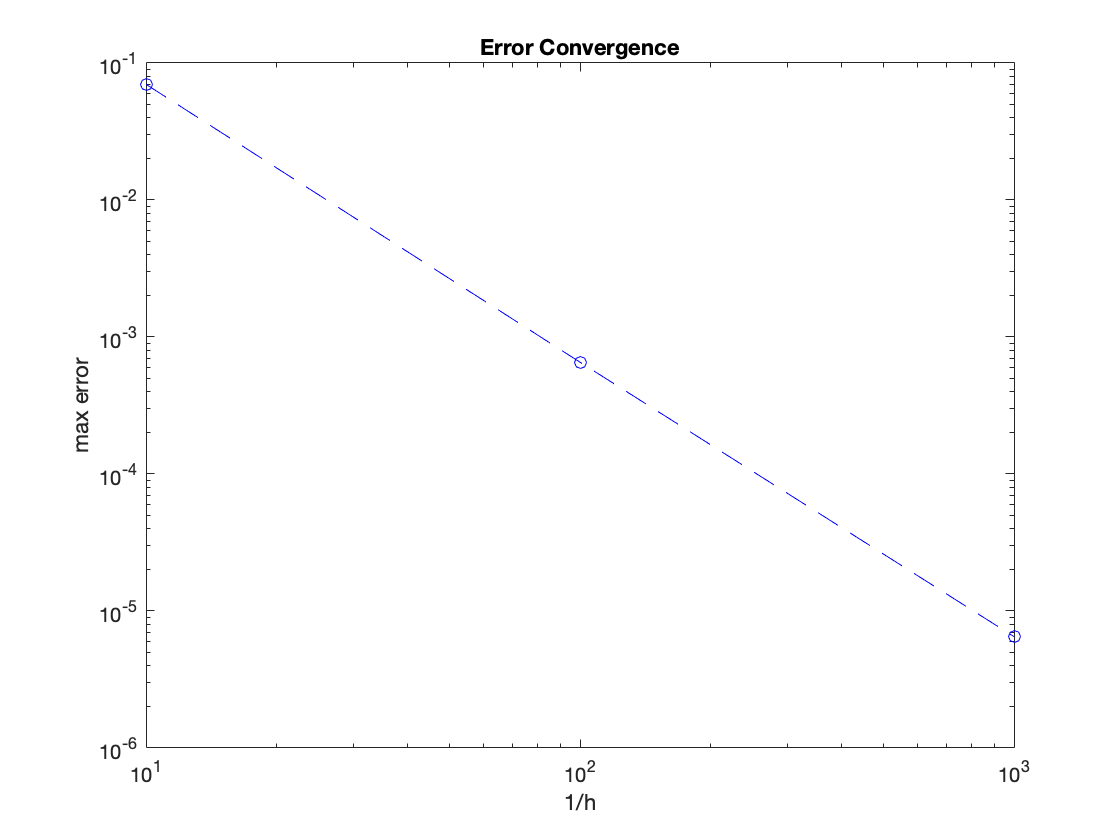

%order of accuracy is roughly 2
h10 = 1/10;
h100 = 1/100;
h1000 = 1/1000;
h = [h10 h100 h1000];
emax = [emax10 emax100 emax1000];
loglog(1./h, emax,'b--o')
title('Error Convergence');
xlabel('1/h');
ylabel('max error');

## Problem 2 (30 points) 

The code block below will place into your workspace a set of points that are arranged in a “**face centered cubic**” (FCC) structure such as the crystal lattice structure of copper and nickel. It will also create a graphical representation of that lattice. Function `fcc` is defined at the end of this file, as required in a MATLAB Live Script.  Note that the function `fcc` adds abit of randomness to the point positions to make the exercise more realistic. 

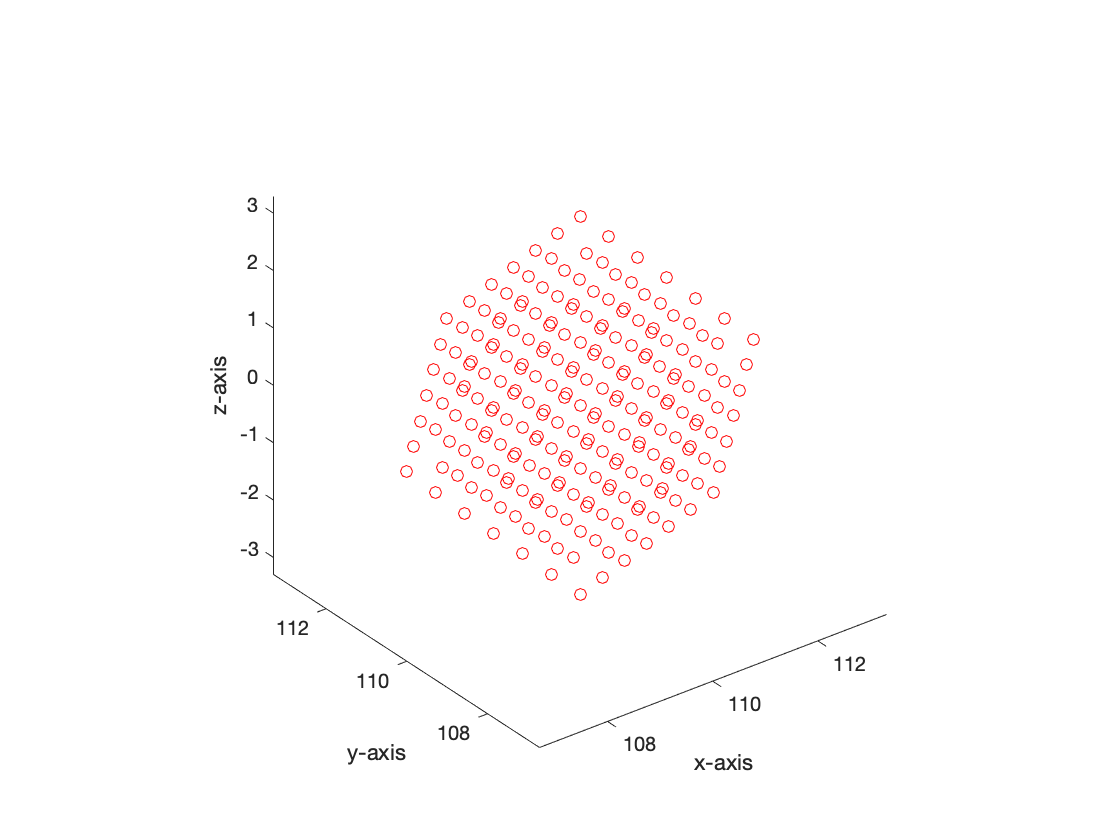

% Initialize/reset memory, figure, and prompt window.
clear; clc;

[Xcoord,Ycoord,Zcoord]=fcc();   % See fcc function at the bottom of this file.
plot3(Xcoord(:),Ycoord(:),Zcoord(:),'ro') 
xlabel('x-axis')
ylabel('y-axis')
zlabel('z-axis')
axis equal

a) (5 points) How many points lie in the plane z=0?  Here we will define the plane z=0 such that the z coordinate is within +/-0.01 of zero.

% Place your code here and call number of the points N_0.
N_0 = 0;
for iz = 1:size(Zcoord)
    if abs(Zcoord(iz))<=0.01
        N_0 = N_0+1;
    end
end
N_0

N_0 = 49

b) (10 points) What is the smallest distance between two distinct points in the whole set?    

% Place your code here and call the minimum distance dist_min
dist_min = Inf;
for i = 1:size(Xcoord)
    x1 = Xcoord(i);
    y1 = Ycoord(i);
    z1 = Zcoord(i);
    for j = 1:size(Xcoord)
        if i==j
            break
        else
            x2 = Xcoord(j);
            y2 = Ycoord(j);
            z2 = Zcoord(j);
            distance = sqrt(((x2-x1)^2)+((y2-y1)^2)+((z2-z1)^2));
            if distance < dist_min
                dist_min = distance;
            end
        end
        
    end
end
dist_min

dist_min = 0.7731

c) (5 points) What is the smallest perpendicular distance between the plane z=0 and another parallel plane that contains any of the points?  Save your result in a variable named smallest_planar_dist 

% Place your code here and call the minimum perpendicular distance smallest_planar_dist

smallest_planar_dist = Inf;
for iz = 1:size(Xcoord)
    if abs(Zcoord(iz))>0.01
        vert_dist = abs(Zcoord(iz));
        if vert_dist < smallest_planar_dist
            smallest_planar_dist = vert_dist;
        end
    end
end
smallest_planar_dist

smallest_planar_dist = 0.5474

d) (10 points) What is the area of the polygon contained in the plane z=0 that is constructed by connecting the point with the smallest x value on the plane to the point with the largest y value on the plane to the point with the largest x value on the plane to the point with the smallest y value on the plane?  NOTE:  You can use the MATLAB function polyarea if you want to.

% Place your code here and call the area A_poly
x_on_zzero = [];
y_on_zzero = [];
indices = [];
for i = 1:size(Xcoord)
    if abs(Zcoord(i))<=0.01
        indices(end+1) = i;
        x_on_zzero(end+1) = Xcoord(i);
        y_on_zzero(end+1) = Ycoord(i);
    end
end
x_on_zzero

x_on_zzero =   107.2500  106.6999  107.2490  108.3493  107.7991  108.3502  107.7999  108.3501  107.7991  108.3491  109.4515  108.8984  109.4516  108.9000  109.4511  108.9012  109.4497  108.8998  109.4509  108.9010  109.4489  110.0011  110.5496  109.9995  110.5496  109.9986  110.5492  110.0001  110.5500  109.9988  110.5498  110.0004  110.5510  110.0003  111.0999  111.6508  111.1020  111.6510  111.0994  111.6499  111.0993  111.6505  111.1006  112.1995  112.7499  112.1990  112.7489  112.1984  113.3000


y_on_zzero

y_on_zzero =   109.4502  110.0020  110.5516  108.3499  108.8997  109.4481  109.9983  110.5491  111.0996  111.6507  107.2510  107.7996  108.3514  108.8993  109.4499  110.0016  110.5497  111.0992  111.6495  112.1989  112.7499  106.7009  107.2505  107.8002  108.3485  108.8997  109.4503  109.9988  110.5498  111.0986  111.6505  112.2003  112.7493  113.3018  107.8000  108.3499  108.9010  109.4506  109.9996  110.5491  111.1001  111.6488  112.1987  108.9005  109.4491  110.0002  110.5488  111.0993  110.0004


xmin = find(x_on_zzero==min(x_on_zzero));
xmax = find(x_on_zzero==max(x_on_zzero));
ymin = find(y_on_zzero==min(y_on_zzero));
ymax = find(y_on_zzero==max(y_on_zzero));
xvals = [Xcoord(xmin) Xcoord(xmax) Xcoord(ymin) Xcoord(ymax)];
yvals = [Ycoord(xmin) Ycoord(xmax) Ycoord(ymin) Ycoord(ymax)];
A_poly = polyarea(xvals,yvals)

A_poly = 0.3026

## Problem 3 (20 points) 

The following data in the form y=y(x) has been obtained as part of an experiment (see [1] for more detail)

[[1]](http://proceedings.asmedigitalcollection.asme.org/proceeding.aspx?articleid=2591878) Kathryn M. Olesnavage and Amos G. Winter, “Design and Preliminary Testing of a Prototype for Evaluating Lower Leg Trajectory Error as an Optimization Metric for Prosthetic Feet”, ASME Conference, DETC2016-60565 (2016).

clear;close all;clc

x=[0.2 0.3 0.4 0.5]; % data (portion in gait cycle, so dimensionless)
y=[0.082 0.083 0.089 0.115]; % data (ankle position in meters)
plot(x,y,'ko');
xlabel('x (percent of gait cycle, dimensionless)');
ylabel('y (ankle position, meters');           

a) (5 points) Use linear interpolation to estimate the value of y at x=0.41.  Place your result in a variable named "y_linear". 

% Put your work here:
xq = 0.41;
y_linear = interp1(x,y,xq,"linear")

y_linear = 0.0916

b) (5 points) Use cubic spline interpolation to estimate the value of y at x=0.41.  Place your result in a variable named "y_spline". 

% Put your work here:

y_spline = spline(x,y,xq)

y_spline = 0.0905

c) (5 points) Create a plot to illustrate the approaches from parts (a) and (b). On the same figure, plot the two  interpolating functions you developed by sampling them at 1000 equi-spaced points in the interval `0.2≤x≤0.5`. In summary, the figure should contain plots of

- The raw data, shown by black circles.

- The linear interpolating function denoted by a blue line with the prediction at x=0.41 shown as a blue x.

- The cubic spline interpolant denoted by a red line with the prediction at x=0.41 shown as a red o.

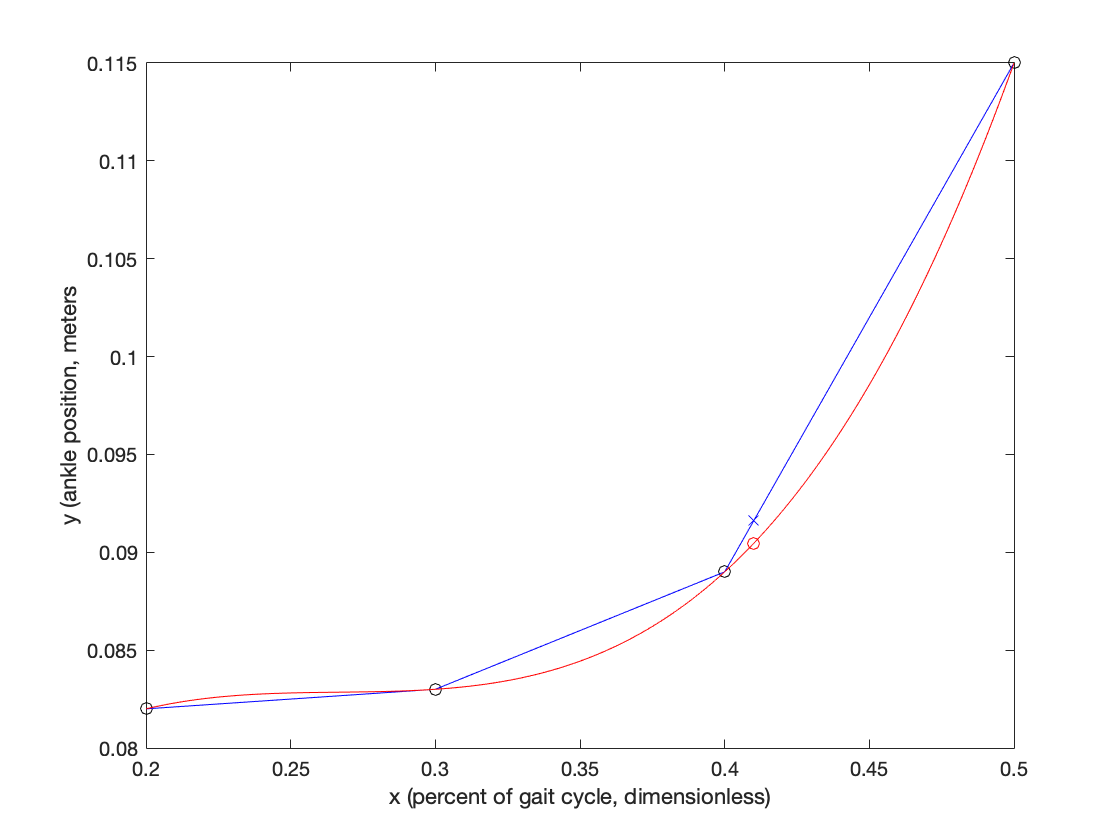

% Put your work here:
hold on
x=[0.2 0.3 0.4 0.5]; % data (portion in gait cycle, so dimensionless)
y=[0.082 0.083 0.089 0.115]; % data (ankle position in meters)
xq = 0.41;

plot(x,y,"ko")
int = linspace(0.2,0.5,1000);
plot(int,interp1(x,y,int,"linear"),"b-")
plot(xq,y_linear,"bx")
plot(int,spline(x,y,int),"r-")
plot(xq,y_spline,"ro")

d) (5 points) Briefly discuss the following:

- A potential benefit of using a higher order interpolating function.

- A potential hazard of using a higher order interpolating function.

Provide your **comments** here:

% 1. A potential benefit of using a higher order itnerpolating function is
% having a smaller error.
%
% 2. A potential hazard of using a higher order interpolating function is
% that if the original data had an outlier the higher order interpolating
% function would be more prone to yielding a greater error.

## Problem 4 (10 points) 

a) (5 points) Use **rectangle, left integration rule** (without using a MATLAB built-in function) to evaluate the area under the curve of `y=2*sin(x^2)` in the interval $-0\ldotp 5\le x<1$. By choosing sufficiently small h, make sure that the error in your numerical integration is at most 1e-4 (the difference between your result and the true area is at most 1e-4). You should not assume that you know the true value of the integral. Instead, use the results given in the course notes to bound your numerical error.  HINT:  You'll need to estimate the maximum slope of the function over the interval [a,b]. 


$$| I - I_h | \le \frac{b-a}{2} \max_{i \in \{ 1, \dots, N-1 \}} \; \max_{x  \in  S_i} \; |f'(x)|\, h \;$$


clear;close all;clc
% Put your code here and call the area Ih:
% derivative of eqn = 4xcos(x^2)
% interval -0.5<x<1
% max abs(slope) in interval is approx 2.567
max_slope = 2.567;
b = 1;
a = -0.5;
% error_bound = ((b-a)/2)*2.567*h;
max_h = (10^-4)/(((b-a)/2)*2.567)

max_h = 5.1941e-05

h = 5*10.^(-5);
num_of_intervals = (b-a)/h;
xspan = linspace(a,b,num_of_intervals);
Ih = 0;
for i = 1:num_of_intervals-1
    Ih = Ih + h*(f(xspan(i)));
end
Ih

Ih = 0.7034

b) (2 points) Include an explanation of how you chose h so that the error would not exceed the limit and also so that the discretization is not exceedingly fine.  You can incorporate your comments in the code above if you wish.

% The max h I could  have was around 5.1941e-05, so I chose 5e-05, as the
% h, a value in the same order of 10 as the max h value allowed so as
% to keep the discretization not exceedingly fine while keeping the error
% below 1e-04.

c) (3 points) Check that this error bound formula does indeed allow you to choose the discretization length, h, in accordance with the above requirement (the difference between your result and the true area is at most 1e-4).  NOTE:  You can use the built in "integral" to get the "exact" solution because its error will be much smaller than your specification. 

% Provide your code here
fun = @(x) 2*sin(x.^2);
I = integral(fun,-0.5,1);
error = I-Ih;
error <= 10^(-4)

ans = logical
   1


## Problem 5 (15 points) 

Many aircraft that require low drag are designed to have an elliptical spanwise distribution of lift force:


$$l=l_o \sqrt{1-{\left(\frac{2x}{s}\right)}^2 }$$


where $s$ is the span of the wing, $x$ is the position along the span, $l_o$ is the lift per unit span at the wing root where $x=0$.  Note that span is defined to run from wingtip to wingtip, but we will be analyzing just the lift from the root to the right tip where $x=\frac{s}{2}$ and $l=0$.

Below is a plot of the lift distribution on a wing of span 7 meters.

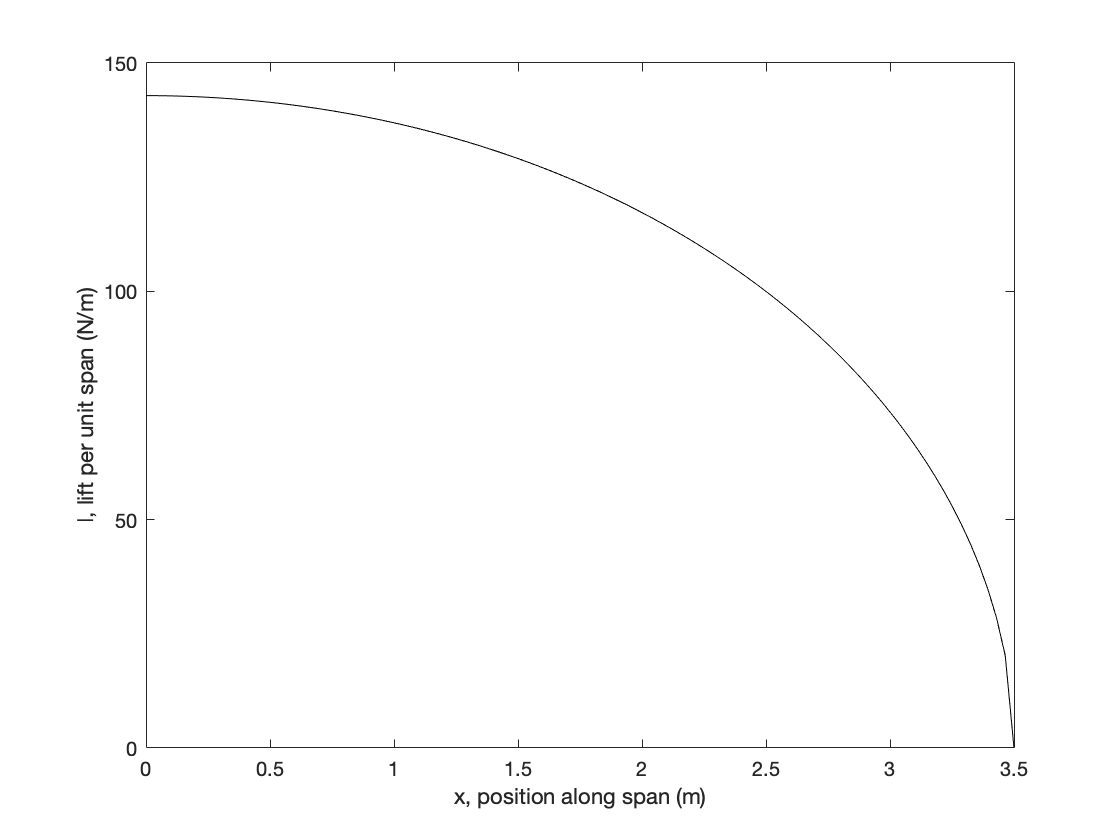

clear;close all;clc

s=7;
lo=1000/7;
x=linspace(0,s/2);
l=@(x) lo*sqrt(1-(2*x/s).^2);
plot(x,l(x),'k')
xlabel('x, position along span (m)')
ylabel('l, lift per unit span (N/m)')

The lift distribution acts on the wing to generate shear forces and bending moments.  As you will learn (or have already learned) in 2.001, the shear force and bending moments are expressed as integrals. 


$$V_b \left(x\right)-V_a \left(x\right)=-\int_a^b w\left(x\right)\textrm{dx}$$



$$M_b \left(x\right)-M_a \left(x\right)=\int_a^b V\left(x\right)\textrm{dx}$$


Note that due to sign conventions in aerodynamics and solid mechanics, in this problem $w\left(x\right)=-l\left(x\right)$.  Note also that because the wing is free of constraints at the end, we can infer that  $V\left(\frac{s}{2}\right)=0$ and $M\left(\frac{s}{2}\right)=0$.

a) (5 points) Write your own code for implementing the **trapezoid rule** on a uniform grid with `N`=100 points and use it to compute the shear force at the root of the wing $x=0$ and save your results in a variable named V_one_two.

Note: In this part, you can**NOT** use the MATLAB built-in trapz function.

% Enter your code here:
N = 100;
xvals = linspace(0,s/2,N);
w=@(x) -l(x);
V_one_two = 0;
for i = 1:N-1
    V_one_two = V_one_two - ((xvals(i+1)-xvals(i))/2)*(w(xvals(i))+w(xvals(i+1)));
end
V_one_two

V_one_two =           392.549897264327


b) (5 points) Use the "integral" function to estimate the integral from (a) by a different approach.  Save your result in a variable named "exact".   Verify the correctness of your solution to part (a) by checking that the absolute difference between the two results moderate, (should be less than 0.1% in relative terms).

% Enter your code here:
exact = -integral(w,0,s/2);
abs(V_one_two-exact)<0.001*exact

ans = logical
   1


c) (5 points) Write a code to make a shear and bending moment diagram for the wing.  Calculate the shear and bending moments at 100 different locations stored in a 1xN matrix named xp as defined below.  Store your results in 1xN matrices named Vp and Mp.   Note that Vp(end) and Mp(end) are zero by definition because the integrals have lower limiuts amtching the and upper limits when $x=\frac{b}{2}$, so they are initialized to the correct values by the starter code below.  Please use the subplot function so that the two plots are aligned as they are conventionally as in the example below.   

NOTE: In general, the formulas for shear and bending moment include constants of integration which have to be established by undertsanding and applying knowledge of the boundary conditions.  In this case, with the wing being free of contraints at the tip, the shear and bending moments are therefore zero at the tip.  

You **CAN** use MATLAB built-in **trapz** function for this part.

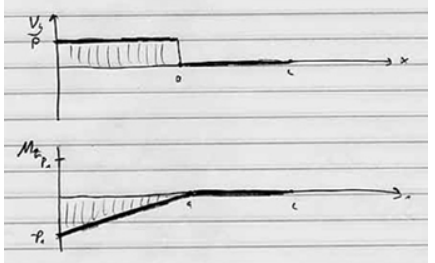

[lec5.pdf (mit.edu)](https://ocw.mit.edu/courses/mechanical-engineering/2-001-mechanics-materials-i-fall-2006/lecture-notes/lec5.pdf)

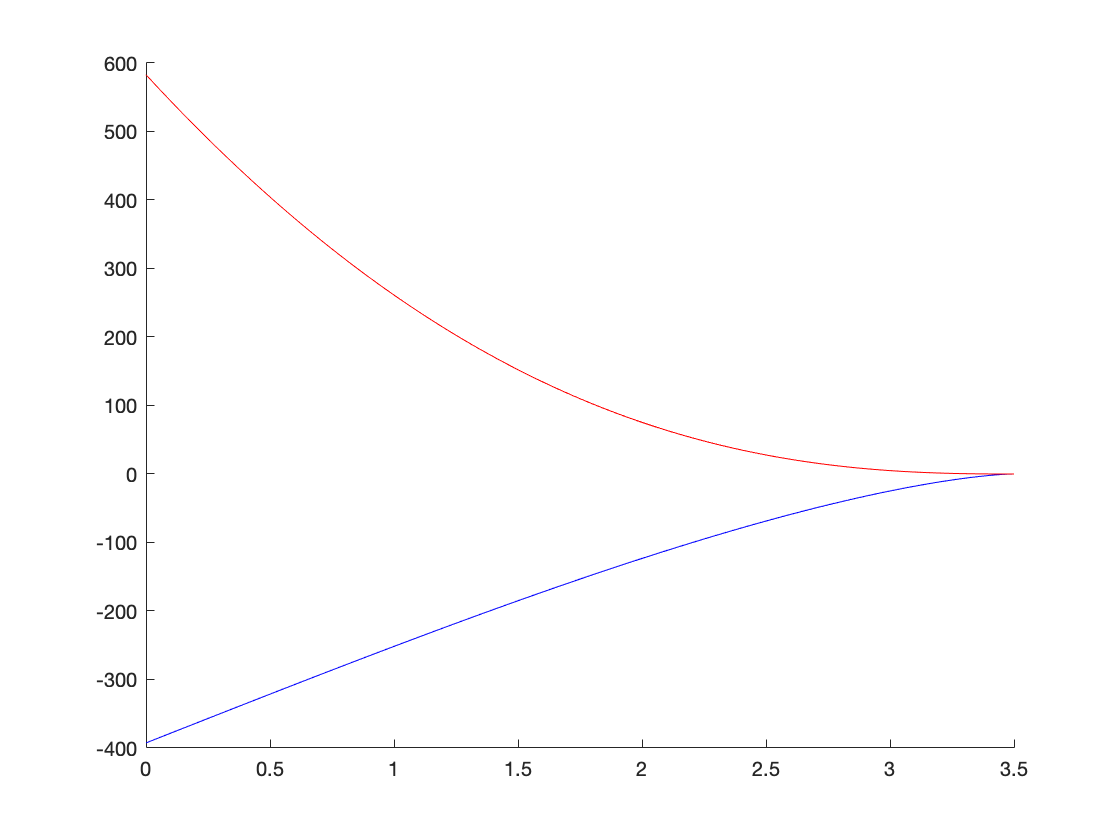

% This is starter code to save you some effort.
N=100;
xi=linspace(0,3.5,N);
Vp(N)=0; % initializing shear at the wing tip as suggested above
Mp(N)=0; % initializing moment at the wing tip as suggested above
Wp = w(xi);
% Put your code here
for i = 1:N-1
    Vp(N-i) = Vp(N-i+1)+trapz([xi(N-i) xi(N-i+1)],[Wp(N-i) Wp(N-i+1)]);
end
for i = 1:N-1
    Mp(N-i) = Mp(N-i+1)-trapz([xi(N-i) xi(N-i+1)],[Vp(N-i) Vp(N-i+1)]);
end
clf;
hold on
plot(xi,Vp,"b-")
plot(xi,Mp,"r-")

% NOTE: A good check on signs is that positive moments must result in upward curvature 

function [Xcoord, Ycoord, Zcoord]=fcc()
% This function definition is used in Problem No. 2.
Xcoord=[107.25	107.25	106.7	107.25	107.25	108.35	108.35	108.35	107.8	107.8	108.35	108.35	107.8	108.35	108.35	107.8	108.35	108.35...
   	107.8	107.8	108.35	108.35	107.8	107.8	108.35	108.35	108.35	107.8	108.35	108.35	109.45	109.45	109.45	108.9	108.9	109.45...
   	109.45	108.9	109.45	109.45	109.45	108.9	108.9	109.45	109.45	108.9	108.9	109.45	109.45	108.9	108.9	109.45	109.45	108.9...
   	109.45	109.45	108.9	109.45	109.45	108.9	108.9	109.45	109.45	108.9	108.9	109.45	109.45	108.9	108.9	109.45	109.45	108.9...
   	108.9	109.45	109.45	109.45	108.9	109.45	109.45	108.9	108.9	109.45	109.45	108.9	108.9	109.45	109.45	109.45	108.9	109.45...
   	109.45	110	110	110.55	110	110	110	110.55	110.55	110	110	110.55	110.55	110	110	110.55	110	110 ...
   	110	110.55	110.55	110	110	110.55	110.55	110	110	110.55	110.55	110	110	110.55	110.55	110	110	110.55...
   	110	110	110.55	110	110	110.55	110.55	110	110	110.55	110.55	110	110	110.55	110.55	110	110	110.55...
   	110.55	110	110	110.55	110.55	110	110	110	110.55	110	110	110.55	110.55	110	110	110.55	110.55	110 ...
   	110	110.55	110.55	110	110	110	110.55	110	110	110.55	110.55	110	110	110	111.1	111.1	111.65	111.1...
   	111.1	111.1	111.65	111.65	111.1	111.1	111.65	111.65	111.1	111.1	111.65	111.1	111.1	111.65	111.1	111.1	111.65	111.65...
   	111.1	111.1	111.65	111.65	111.1	111.1	111.65	111.65	111.1	111.1	111.1	111.65	111.1	111.1	111.65	111.65	111.1	111.1...
   	111.1	112.2	112.2	112.75	112.2	112.2	112.75	112.2	112.2	112.75	112.75	112.2	112.2	112.2	113.3]';
Ycoord=[109.45	110	110	110.55	110	108.35	109.45	108.9	109.45	108.9	109.45	108.9	109.45	109.45	110	110	110.55	110 ...
   	110.55	110	110.55	110	110.55	110	110.55	110	111.1	111.1	111.65	111.1	107.25	108.35	107.8	108.35	107.8	108.35...
   	107.8	108.35	108.35	109.45	108.9	109.45	108.9	109.45	108.9	109.45	108.9	109.45	108.9	109.45	108.9	109.45	108.9	109.45...
   	109.45	110	110	110.55	110	110.55	110	110.55	110	110.55	110	110.55	110	110.55	110	110.55	110	110.55...
   	110	110.55	110	111.1	111.1	111.65	111.1	111.65	111.1	111.65	111.1	111.65	111.1	111.65	111.1	112.2	112.2	112.75...
   	112.2	107.25	106.7	107.25	107.25	108.35	107.8	108.35	107.8	108.35	107.8	108.35	107.8	108.35	107.8	108.35	108.35	109.45...
   	108.9	109.45	108.9	109.45	108.9	109.45	108.9	109.45	108.9	109.45	108.9	109.45	108.9	109.45	108.9	109.45	108.9	109.45...
   	109.45	110	110	110.55	110	110.55	110	110.55	110	110.55	110	110.55	110	110.55	110	110.55	110	110.55...
   	110	110.55	110	110.55	110	110.55	110	111.1	111.1	111.65	111.1	111.65	111.1	111.65	111.1	111.65	111.1	111.65...
   	111.1	111.65	111.1	111.65	111.1	112.2	112.2	112.75	112.2	112.75	112.2	112.75	112.2	113.3	108.35	107.8	108.35	108.35...
   	109.45	108.9	109.45	108.9	109.45	108.9	109.45	108.9	109.45	108.9	109.45	109.45	110	110	110.55	110	110.55	110 ...
   	110.55	110	110.55	110	110.55	110	110.55	110	110.55	110	111.1	111.1	111.65	111.1	111.65	111.1	111.65	111.1...
   	112.2	109.45	108.9	109.45	109.45	110	110	110.55	110	110.55	110	110.55	110	111.1	110]';
Zcoord=[0	-0.55	0	0	0.55	0	-1.1	-0.55	-0.55	0	0	0.55	0.55	1.1	-1.65	-1.1	-1.1	-0.55...
   	-0.55	0	0	0.55	0.55	1.1	1.1	1.65	-0.55	0	0	0.55	0	-1.1	-0.55	-0.55	0	0 ...
   	0.55	0.55	1.1	-2.2	-1.65	-1.65	-1.1	-1.1	-0.55	-0.55	0	0	0.55	0.55	1.1	1.1	1.65	1.65...
   	2.2	-2.75	-2.2	-2.2	-1.65	-1.65	-1.1	-1.1	-0.55	-0.55	0	0	0.55	0.55	1.1	1.1	1.65	1.65...
   	2.2	2.2	2.75	-1.65	-1.1	-1.1	-0.55	-0.55	0	0	0.55	0.55	1.1	1.1	1.65	-0.55	0	0 ...
   	0.55	-0.55	0	0	0.55	-1.65	-1.1	-1.1	-0.55	-0.55	0	0	0.55	0.55	1.1	1.1	1.65	-2.75...
   	-2.2	-2.2	-1.65	-1.65	-1.1	-1.1	-0.55	-0.55	0	0	0.55	0.55	1.1	1.1	1.65	1.65	2.2	2.2...
   	2.75	-3.3	-2.75	-2.75	-2.2	-2.2	-1.65	-1.65	-1.1	-1.1	-0.55	-0.55	0	0	0.55	0.55	1.1	1.1...
   	1.65	1.65	2.2	2.2	2.75	2.75	3.3	-2.2	-1.65	-1.65	-1.1	-1.1	-0.55	-0.55	0	0	0.55	0.55...
   	1.1	1.1	1.65	1.65	2.2	-1.1	-0.55	-0.55	0	0	0.55	0.55	1.1	0	-0.55	0	0	0.55...
   	-1.65	-1.1	-1.1	-0.55	-0.55	0	0	0.55	0.55	1.1	1.1	1.65	-2.2	-1.65	-1.65	-1.1	-1.1	-0.55...
   	-0.55	0	0	0.55	0.55	1.1	1.1	1.65	1.65	2.2	-1.1	-0.55	-0.55	0	0	0.55	0.55	1.1...
   	0	-0.55	0	0	0.55	-1.1	-0.55	-0.55	0	0	0.55	0.55	1.1	0	0]';
Xcoord=Xcoord+0.001*randn(length(Xcoord),1);
Ycoord=Ycoord+0.001*randn(length(Xcoord),1);
Zcoord=Zcoord+0.001*randn(length(Xcoord),1);
end
function y=f(x)
    y = 2*sin(x.^2);
end